# MAE 384 Group Project

### Team: Sicko Code

### Contributors: Hayden Redmond, Ottavia Formicone, Brady Bauer, Ava Masche

## Part 1: Modeling disease spread using SIR model

            
$$\begin{array}{l}
\textrm{Susceptible}\;\textrm{individuals}:\;\frac{\textrm{dS}\left(t\right)}{\textrm{dt}}=-\frac{\beta }{N}S\left(t\right)I\left(t\right)\\
\textrm{Infected}\;\textrm{individuals}:\;\;\;\;\;\;\;\;\;\frac{\textrm{dI}\left(t\right)}{\textrm{dt}}=\frac{\beta }{N}S\left(t\right)I\left(t\right)-\gamma I\left(t\right)\\
\textrm{Recovered}\;\textrm{individuals}:\;\;\;\frac{\textrm{dR}\left(t\right)}{\textrm{dt}}=\gamma I\left(t\right)\\
\textrm{Total}\;\textrm{population}:\;\;\;\;\;\;\;\;\;\;\;\;\;\;N=S\left(t\right)+I\left(t\right)+R\left(t\right)\\
\\
\beta =\textrm{transmission}\;\textrm{rate}\;\;\;\;\;\;\;\;\;\;\;\;\;\;\gamma =\textrm{recovery}\;\textrm{rate}
\end{array}$$


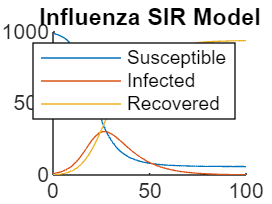

clear; clc; close all
Influenza_Tran_Rate = 0.3;
Influenza_Recov_Rate = 0.1;

COVID_19_Tran_Rate = 1;
COVID_19_Recov_Rate = 0.1;

Measles_Tran_Rate = 2;
Measles_Recov_Rate = 0.2;

[Flu_S,Flu_I,Flu_R] = SIR_Model(990,10,0,100,1,Influenza_Tran_Rate,Influenza_Recov_Rate);
[COVID_S,COVID_I,COVID_R] = SIR_Model(990,10,0,100,1,COVID_19_Tran_Rate,COVID_19_Recov_Rate);
[Measles_S,Measles_I,Measles_R] = SIR_Model(990,10,0,100,1,Measles_Tran_Rate,Measles_Recov_Rate);

Time_Step_1Day = 0:1:100;

figure(1)
hold on
title('Influenza SIR Model')
plot(Time_Step_1Day,Flu_S)
plot(Time_Step_1Day,Flu_I)
plot(Time_Step_1Day,Flu_R)
legend('Susceptible','Infected','Recovered')
xlim([0 100])
ylim([0 1000])
hold off

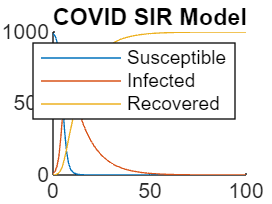


figure(2)
hold on
title('COVID SIR Model')
plot(Time_Step_1Day,COVID_S)
plot(Time_Step_1Day,COVID_I)
plot(Time_Step_1Day,COVID_R)
legend('Susceptible','Infected','Recovered')
xlim([0 100])
ylim([0 1000])
hold off

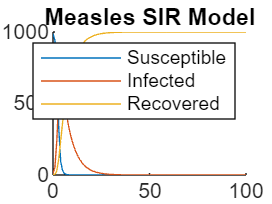


figure(3)
hold on
title('Measles SIR Model')
plot(Time_Step_1Day,Measles_S)
plot(Time_Step_1Day,Measles_I)
plot(Time_Step_1Day,Measles_R)
legend('Susceptible','Infected','Recovered')
xlim([0 100])
ylim([0 1000])
hold off

#### Discussion:

blah blah blah

## Part 2: Interpolation

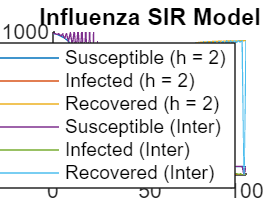

## Part 3: Least-Squares

[ln_I, Initial_Infected_est, Tran_Rate_est, k_est, t_data, X, theta] = Linear_Least_Squares(990,10,0,30,1,Influenza_Tran_Rate,Influenza_Recov_Rate);
disp('Estimated Parameters:');

Estimated Parameters:


fprintf('I(0) (Estimated): %.2f\n', Initial_Infected_est);

I(0) (Estimated): 17.91


fprintf('k (Estimated): %.4f\n', k_est);

k (Estimated): 0.1149


fprintf('Tran_Rate (Estimated): %.4f\n', Tran_Rate_est);

Tran_Rate (Estimated): 0.2171


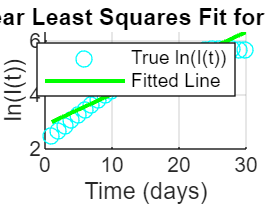


% Plot Results
figure(10);
scatter(t_data, ln_I, 'co', 'DisplayName', 'True ln(I(t))');
hold on;
plot(t_data, X * theta, 'g-', 'LineWidth', 1.5, 'DisplayName', 'Fitted Line');
xlabel('Time (days)');
ylabel('ln(I(t))');
title('Linear Least Squares Fit for ln(I(t))');
legend;
grid on;
hold off;


[ln_I_10, Initial_Infected_est_10, Tran_Rate_est_10, k_est_10, t_data_10, X_10, theta_10] = Linear_Least_Squares(990,10,0,10,1,Influenza_Tran_Rate,Influenza_Recov_Rate);
disp('Estimated Parameters:');

Estimated Parameters:


fprintf('I(0) (Estimated): %.2f\n', Initial_Infected_est);

I(0) (Estimated): 17.91


fprintf('k (Estimated): %.4f\n', k_est);

k (Estimated): 0.1149


fprintf('Tran_Rate (Estimated): %.4f\n', Tran_Rate_est);

Tran_Rate (Estimated): 0.2171



% Plot Results
figure(12);
scatter(t_data, ln_I, 'co', 'DisplayName', 'True ln(I(t))');
hold on;
plot(t_data, X * theta, 'g-', 'LineWidth', 1.5, 'DisplayName', 'Fitted Line');
xlabel('Time (days)');
ylabel('ln(I(t))');
title('Linear Least Squares Fit for ln(I(t))');
legend;
grid on;
hold off;

**Discussion**

Blah Blah Blah

## Part 4: Fourier Analysis

clear; clc; close all


type Periodic_SIR_Model.m

function [S,I,R,Time] = Periodic_SIR_Model(Initial_Susceptible,Initial_Infected,Initial_Recovered,Sim_Time,Time_Step,Recov_Rate,Initial_Transmission_Rate,Amplitude,Angular_Frequency)



Time = 0:Time_Step:Sim_Time;
Tran_Rate = Initial_Transmission_Rate.*(1 + Amplitude .* Angular_Frequency .* Time);


  Initial_Counts = [Initial_Susceptible,Initial_Infected,Initial_Recovered];
   
    N = sum(Initial_Counts);

    Solution = zeros(length(Time),3);
    Solution(1,:) = Initial_Counts;
    
    SIR_System = @(Time,Solution_Array,Tran_Rate) [
        -(Tran_Rate / N) * Solution_Array(1) * Solution_Array(2);
        (Tran_Rate / N) * Solution_Array(1) * Solution_Array(2) - Recov_Rate * Solution_Array(2);
        Recov_Rate * Solution_Array(2);
    ];

    for i = 1:(length(Time) - 1)
        Solution_Transposed = Solution(i,:)';

        k1 = SIR_System(Time(i),Solution_Transposed,Tran_Rate(i)) * Time_Step;
        k2 = SIR_System(Time(i) + (Time_Step / 2), Solution_Transposed + (k1 / 2),Tra

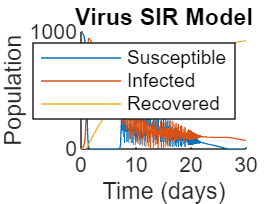

Recov_Rate = 0.1;
Initial_Tran_Rate = 0.3;
Amplitude = 5;
Angular_Frequency = 2*pi;
Duration = 30;
timeStep = 0.1;


[Virus_S,Virus_I,Virus_R,Time] = Periodic_SIR_Model(990,10,0,Duration,timeStep,Recov_Rate,Initial_Tran_Rate,Amplitude,Angular_Frequency);



figure
hold on
title('Virus SIR Model')
plot(Time,Virus_S)
plot(Time,Virus_I)
plot(Time,Virus_R)
legend('Susceptible','Infected','Recovered')
xlabel('Time (days)');
ylabel('Population');
xlim([0 30])
ylim([0 1000])
hold off

In the above figure of the SIR model for the given virus with a periodic transmission rate, fluctuations can mostly be seem in the infected and susceptible trend lines. This behavior starts to take to effect between day seven and day 22 and has a decreasing envelope through the oscillatory phase.

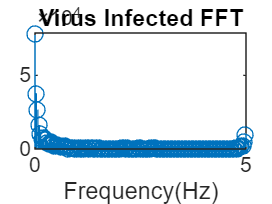


Virus_I_FFT = fft(Virus_I);
Virus_R_FFT = fft(Virus_R);
Virus_S_FFT = fft(Virus_S);

freq = 1/Duration*(0:(Duration/(timeStep*2)));



figure
stem(freq, abs(Virus_I_FFT(1:(Duration/(timeStep*2))+1)));
title('Virus Infected FFT')
xlabel('Frequency(Hz)');

In the above figure showing the frequency spectrum of the infected cases there seems to be a frequency peak around 5Hz. This could make phisical sense given that it is a frequency value that would be feasible with the given system.

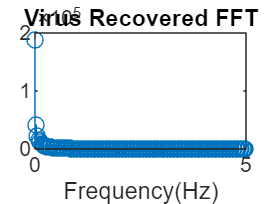

figure
stem(freq, abs(Virus_R_FFT(1:(Duration/(timeStep*2))+1)));
title('Virus Recovered FFT')
xlabel('Frequency(Hz)');

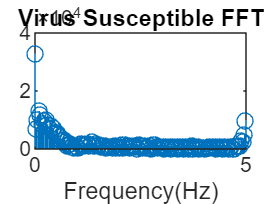






figure
stem(freq, abs(Virus_S_FFT(1:(Duration/(timeStep*2))+1)));
title('Virus Susceptible FFT')
xlabel('Frequency(Hz)');

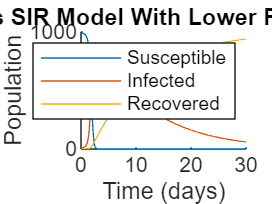



Angular_Frequency = 2*pi*100/365;


[Virus_S,Virus_I,Virus_R,Time] = Periodic_SIR_Model(990,10,0,Duration,timeStep,Recov_Rate,Initial_Tran_Rate,Amplitude,Angular_Frequency);

figure
hold on
title('Virus SIR Model With Lower Frequency')
plot(Time,Virus_S)
plot(Time,Virus_I)
plot(Time,Virus_R)
legend('Susceptible','Infected','Recovered')
xlabel('Time (days)');
ylabel('Population');
xlim([0 30])
ylim([0 1000])
hold off

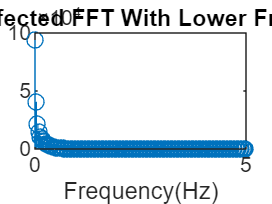



Virus_I_FFT = fft(Virus_I);
Virus_R_FFT = fft(Virus_R);
Virus_S_FFT = fft(Virus_S);

freq = 1/Duration*(0:(Duration/(timeStep*2)));



figure
stem(freq, abs(Virus_I_FFT(1:(Duration/(timeStep*2))+1)));
title('Virus Infected FFT With Lower Frequency')
xlabel('Frequency(Hz)');

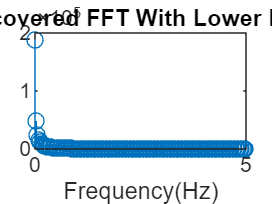

figure
stem(freq, abs(Virus_R_FFT(1:(Duration/(timeStep*2))+1)));
title('Virus Recovered FFT With Lower Frequency')
xlabel('Frequency(Hz)');

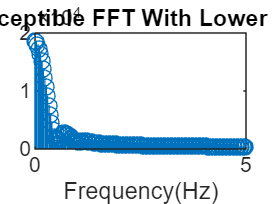




figure
stem(freq, abs(Virus_S_FFT(1:(Duration/(timeStep*2))+1)));
title('Virus Susceptible FFT With Lower Frequency')
xlabel('Frequency(Hz)');

The change in the peak frequency seems to shift to lower values with a lower transmission rate fluctuation frequency. This seems like it would be a reasonable finding given that changes in the fluctuation of the transmission rate would result in diffrent effects on the system as a whole with the same general trend, ie the reduction in transmission rate frequency would decrease the overall fundamental frequencies that build up the individual signals.